clc;        %per pulire la command windows
clear;      %per pulire tutte le variabbili
close all;  %per chiudere tutte le finestre aperte



# **MANIPOLATORE PLANARE A DUE BRACCI **

## Dati

P=zeros(1,2);
P=[1;1.2];                              % punto di partenza

A=zeros(1,2);
A=[1.6;1];                              % punto di arrivo

param=zeros(1,9);
param(1,1)=1;                           % massa braccio 1
param(1,2)=1;                           % massa braccio 2
param(1,3)=1;                           % lunghezza braccio 1
param(1,4)=1;                           % lunghezza braccio 2
param(1,5)=0.5;                         % distanza del baricentro del braccio 1 dall'asse del giunto
param(1,6)=0.5;                         % distanza del baricentro del braccio 1 dall'asse del giunto
param(1,7)=1;                           % inerzia braccio 1
param(1,8)=1;                           % inerzia braccio 2
param(1,9)=9.81;                        % accelerazione gravitazionale


### Estraggo i valori degli angoli e delle posizioni dei giunti

[theta1P,theta2P,theta1A,theta2A,O,C1,C2,P1,A1] = get_theta(P,A,param);

## Visualizzazione delle due configurazioni

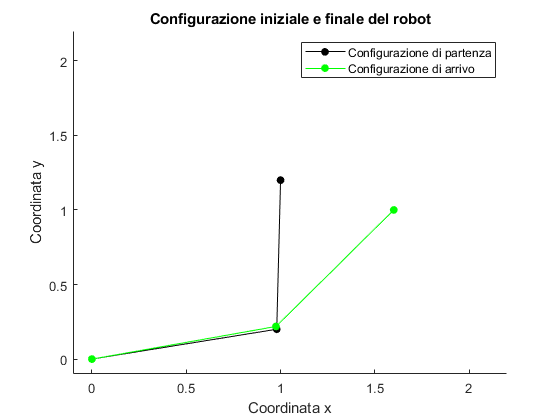

figure
line([O(1,1),C1(1,1),P1(1,1)],[O(2,1),C1(2,1),P1(2,1)],'Color','Black','Marker','.','MarkerSize',20)
hold on
line([O(1,1),C2(1,1),A1(1,1)],[O(2,1),C2(2,1),A1(2,1)],'Color','Green','Marker','.','MarkerSize',20)
xlim([-0.1 param(1,3)+param(1,4)+0.2])
ylim([-0.1 param(1,3)+param(1,4)+0.2])
title('Configurazione iniziale e finale del robot')
legend('Configurazione di partenza','Configurazione di arrivo','Location','northeast')
xlabel('Coordinata x')
ylabel('Coordinata y')
hold off

#### Posizioni dei moventi iniziali e finali e velocità iniziale

q=[theta1P;theta2P]                     % Posizione dei moventi iniziale

q =     0.2016
    1.3490


qA=[theta1A;theta2A]                    % Posizione dei moventi finale

qA =     0.2205
    0.6761


dq0=[0;0];                              % Velocità iniziale

## Regolatore PD

f=100;                                  % Frequenza del controllore
dt=1/f;                                 % Frequenza temporale' del controllore
Kp=60;                                  % Parametro proporzionale regolatore
Kd=7;                                   % Costante derivativa
tau=[0;0];                              % Forza esterna
maxindex=1000;                          % Masssime iterate prima che il codice si fermi senza aver trovato una soluzione

### Raggiungimento della configurazione finale

#### Estrazione dei risultati

[PD_Control_results] = PD_Control(q,qA,param,dt,Kp,Kd,maxindex,10,0,0);   %Tramite la funzione 'Eulero' trovo la posizione finale e la "storia" del percorso fatto dal robot

yE = PD_Control_results.Q';

#### Visualizzazione dei risultati

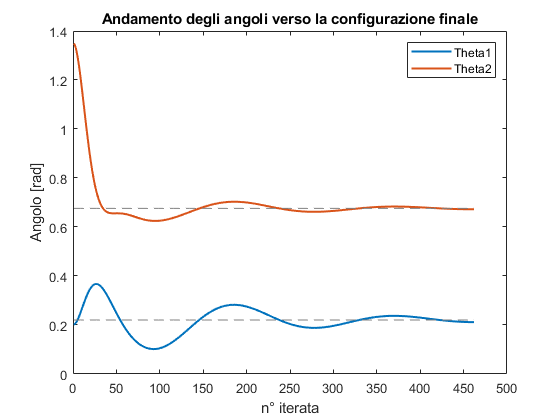

figure                                  % Plotto la "storia" dei valori degli angoli raggiunti prima di arrivare alla configurazione voluta
plot(yE,'LineWidth',1.5)
hold on
plot(repmat(qA,1,length(yE))','color',[0.5 0.5 0.5],'LineStyle','--')
title('Andamento degli angoli verso la configurazione finale')
legend('Theta1','Theta2','Location','northeast')
xlabel('n° iterata')
ylabel('Angolo [rad]')
hold off

## Computed torque

#### Estrazione dei risultati

[Computed_Torque_Results] = Computed_Torque(q,qA,param,dt,Kp,Kd,maxindex,10,0,0);

yCT = Computed_Torque_Results.Q';

#### Visualizzazione dei risultati

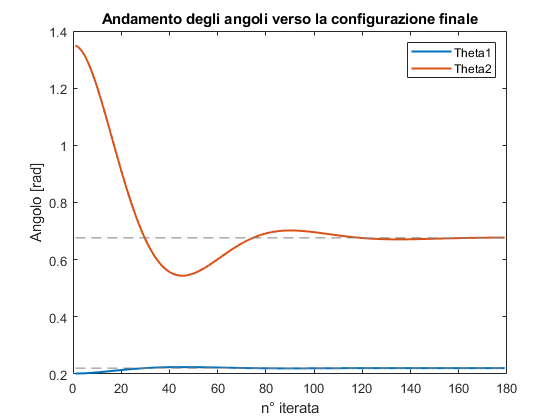

figure                                  % Plotto la "storia" dei valori degli angoli raggiunti prima di arrivare alla configurazione voluta
plot(yCT,'LineWidth',1.5)
hold on
plot(repmat(qA,1,length(yCT))','color',[0.5 0.5 0.5],'LineStyle','--')
title('Andamento degli angoli verso la configurazione finale')
legend('Theta1','Theta2','Location','northeast')
xlabel('n° iterata')
ylabel('Angolo [rad]')
hold off

## Modellazione della superficie

### Posizione della parete

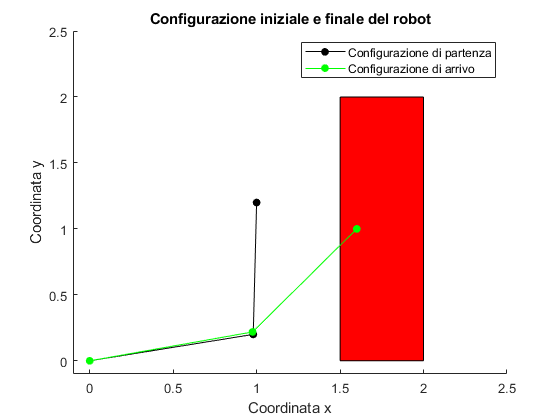

vertice_inferiore=[1.5 0];                          % Modello la parete come un rettangolo
vertice_superiore=[2 2];
spessore_lunghezza=[vertice_superiore-vertice_inferiore];

figure                                              % Disegno il modello con, questa volta, la parete
rectangle('Position',[vertice_inferiore spessore_lunghezza],'FaceColor','Red')
hold on
line([O(1,1),C1(1,1),P1(1,1)],[O(2,1),C1(2,1),P1(2,1)],'Color','Black','Marker','.','MarkerSize',20)
line([O(1,1),C2(1,1),A1(1,1)],[O(2,1),C2(2,1),A1(2,1)],'Color','Green','Marker','.','MarkerSize',20)
axis([-0.1 2.5 -0.1 2.5])
title('Configurazione iniziale e finale del robot')
legend('Configurazione di partenza','Configurazione di arrivo','Location','northeast')
xlabel('Coordinata x')
ylabel('Coordinata y')
hold off

### Modellazione della forza di contatto con la parete

k=100;                                 % costante elastica della parete rigida      %%provo tre superfici morbido e mega rigido
k_elastica=300;
k_morbida=20;
k_calcestruzzo=20000;

### Contatto con controllore PD

[PD_Control_results] = PD_Control(q,qA,param,dt,Kp,Kd,maxindex,vertice_inferiore,vertice_superiore,k);

#### Estrazione dei risultati

y_PD    = PD_Control_results.Q';
E_PD    = PD_Control_results.E;  
dE_PD   = PD_Control_results.dE;
ddQ_PD  = PD_Control_results.ddQ;
dQ_PD   = PD_Control_results.dQ;
Q_PD    = PD_Control_results.Q;
U_PD    = PD_Control_results.U;
TAU_PD  = PD_Control_results.Tau;
ERR1_PD = PD_Control_results.ERR1;
ERR2_PD = PD_Control_results.ERR2;
POSITION_PD = PD_Control_results.POSITION;

#### Visualizzazione della dinamica

Andamento dei moventi

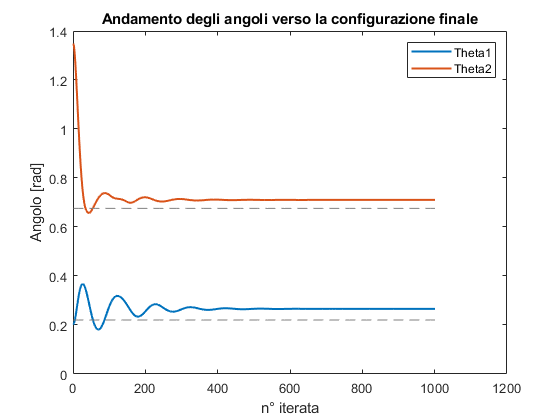

figure                                  % Plotto la "storia" dei valori degli angoli raggiunti prima di arrivare alla configurazione finale
plot(y_PD,'LineWidth',1.5)
hold on
plot(repmat(qA,1,length(y_PD))','color',[0.5 0.5 0.5],'LineStyle','--')
title('Andamento degli angoli verso la configurazione finale')
legend('Theta1','Theta2','Location','northeast')
xlabel('n° iterata')
ylabel('Angolo [rad]')
hold off

Configurazioni del robot

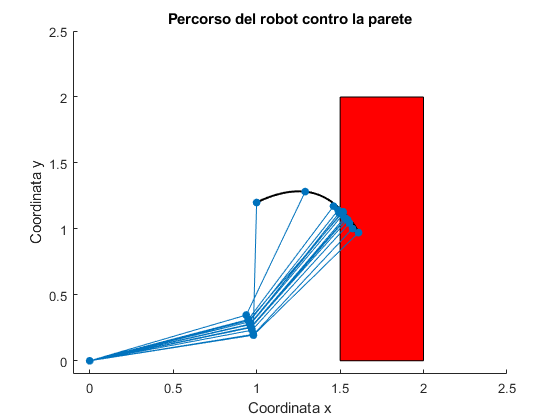

figure                                  % Plotto la "storia" delle configurazioni fino a quella finale
rectangle('Position',[vertice_inferiore spessore_lunghezza],'FaceColor','Red')  % Blocco per rappresentare la parete
hold on
line(POSITION_PD(1,2:length(POSITION_PD)),POSITION_PD(2,2:length(POSITION_PD)),'Color','Black','LineWidth',1.5)   % Vettore con la posizione dell'end effector ad ogni iterata

for jj=2:20:length(POSITION_PD)-700         % Raffiguro le configurazioni del robot ogni 15 iterate, fino alla 300sima iterata, ovvero quella in cui la posizione sembra stabilizzarsi
    [theta1P,theta2P,theta1A,theta2A,O,C1,C2,P1,Position1] = get_theta(P,POSITION_PD(:,jj),param);

    line([O(1,1),C2(1,1),Position1(1,1)],[O(2,1),C2(2,1),Position1(2,1)],'Marker','.','MarkerSize',20)  % Blocco per rappresentare la configurazione
end

axis([-0.1 2.5 -0.1 2.5])
title('Percorso del robot contro la parete')
xlabel('Coordinata x')
ylabel('Coordinata y')
hold off

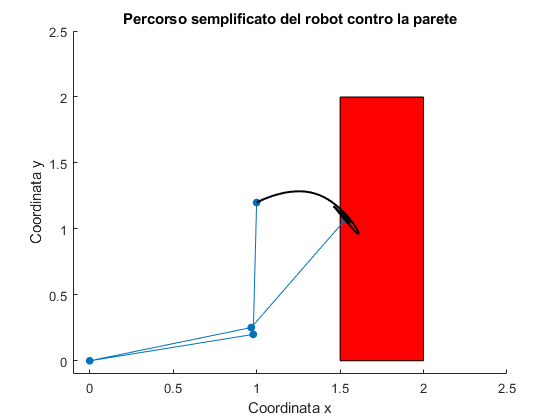

figure                                  % Plotto la "storia" delle configurazioni fino a quella finale
rectangle('Position',[vertice_inferiore spessore_lunghezza],'FaceColor','Red')
hold on
line([O(1,1),C1(1,1),P1(1,1)],[O(2,1),C1(2,1),P1(2,1)],'Marker','.','MarkerSize',20)
line([O(1,1),C2(1,1),Position1(1,1)],[O(2,1),C2(2,1),Position1(2,1)],'Marker','.','MarkerSize',20)
line(POSITION_PD(1,2:length(POSITION_PD)),POSITION_PD(2,2:length(POSITION_PD)),'Color','Black','LineWidth',1.5)
axis([-0.1 2.5 -0.1 2.5])
title('Percorso semplificato del robot contro la parete')
xlabel('Coordinata x')
ylabel('Coordinata y')
hold off

#### Andamento della coppia

Trasmessa ai giunti

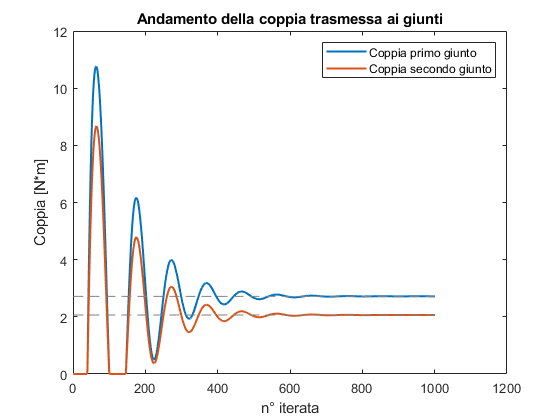

TAU_PD_Finale=TAU_PD(:,1001);
figure                                  % Plotto la "storia" dei valori delle coppie trasmesse ai giunti prima di arrivare alla configurazione finale
plot(TAU_PD','LineWidth',1.5)
hold on
plot(repmat(TAU_PD_Finale',1000,length(TAU_PD)),'color',[0.5 0.5 0.5],'LineStyle','--')    % Plotto la linea asintotica
title('Andamento della coppia trasmessa ai giunti')
legend('Coppia primo giunto','Coppia secondo giunto','Location','northeast')
xlabel('n° iterata')
ylabel('Coppia [N*m]')
hold off

Di controllo

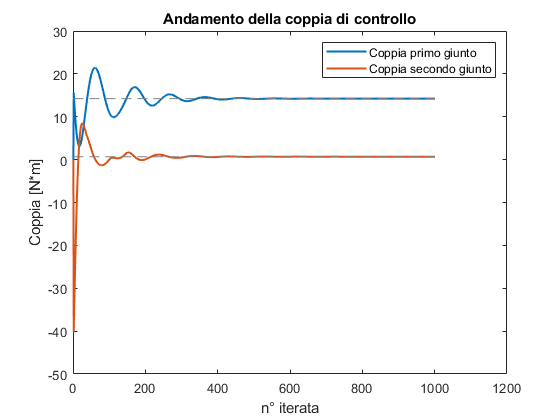

U_PD_Finale_Giunti=U_PD(:,1001);
figure                                  % Plotto la "storia" dei valori delle coppie trasmesse ai giunti prima di arrivare alla configurazione finale
plot(U_PD','LineWidth',1.5)
hold on
plot(repmat(U_PD_Finale_Giunti',1000,length(U_PD)),'color',[0.5 0.5 0.5],'LineStyle','--')    % Plotto la linea asintotica
title('Andamento della coppia di controllo')
legend('Coppia primo giunto','Coppia secondo giunto','Location','northeast')
xlabel('n° iterata')
ylabel('Coppia [N*m]')
hold off

### Contatto con Computed torque controller

[Computed_Torque_Results] = Computed_Torque(q,qA,param,dt,Kp,Kd,maxindex,vertice_inferiore,vertice_superiore,k);

#### Estrazione dei risultati

y_CT    = Computed_Torque_Results.Q';
E_CT    = Computed_Torque_Results.E;  
dE_CT   = Computed_Torque_Results.dE;
ddQ_CT  = Computed_Torque_Results.ddQ;
dQ_CT   = Computed_Torque_Results.dQ;
Q_CT    = Computed_Torque_Results.Q;
U_CT    = Computed_Torque_Results.U;
TAU_CT  = Computed_Torque_Results.Tau;
ERR1_CT = Computed_Torque_Results.ERR1;
POSITION_CT = Computed_Torque_Results.POSITION;

#### Visualizzazione della dinamica

Andamento dei moventi

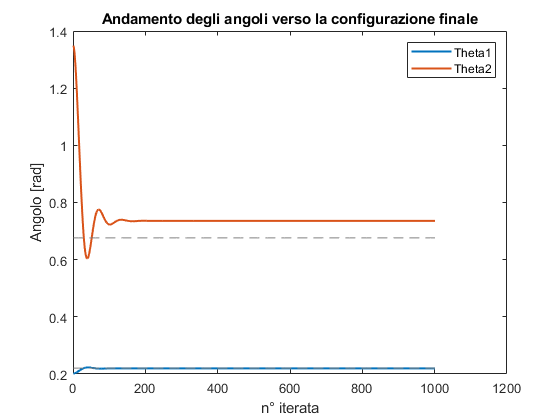

figure                                  % Plotto la "storia" dei valori degli angoli raggiunti prima di arrivare alla configurazione finale
plot(y_CT,'LineWidth',1.5)
hold on
plot(repmat(qA,1,length(y_CT))','color',[0.5 0.5 0.5],'LineStyle','--')
title('Andamento degli angoli verso la configurazione finale')
legend('Theta1','Theta2','Location','northeast')
xlabel('n° iterata')
ylabel('Angolo [rad]')
hold off

Configurazioni del robot

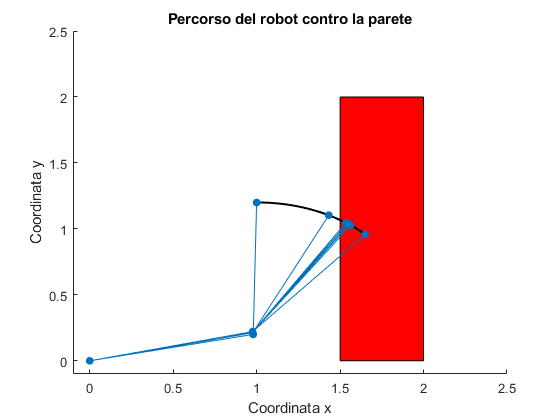

figure                                  % Plotto la "storia" delle configurazioni fino a quella finale
rectangle('Position',[vertice_inferiore spessore_lunghezza],'FaceColor','Red')  % Blocco per rappresentare la parete
hold on
line(POSITION_CT(1,2:length(POSITION_CT)),POSITION_CT(2,2:length(POSITION_CT)),'Color','Black','LineWidth',1.5)   % Vettore con la posizione dell'end effector ad ogni iterata

for jj=2:20:length(POSITION_CT)-700         % Raffiguro le configurazioni del robot ogni 15 iterate, fino alla 300sima iterata, ovvero quella in cui la posizione sembra stabilizzarsi
    [theta1P,theta2P,theta1A,theta2A,O,C1,C2,P1,Position1] = get_theta(P,POSITION_CT(:,jj),param);

    line([O(1,1),C2(1,1),Position1(1,1)],[O(2,1),C2(2,1),Position1(2,1)],'Marker','.','MarkerSize',20)  % Blocco per rappresentare la configurazione
end

axis([-0.1 2.5 -0.1 2.5])
title('Percorso del robot contro la parete')
xlabel('Coordinata x')
ylabel('Coordinata y')
hold off

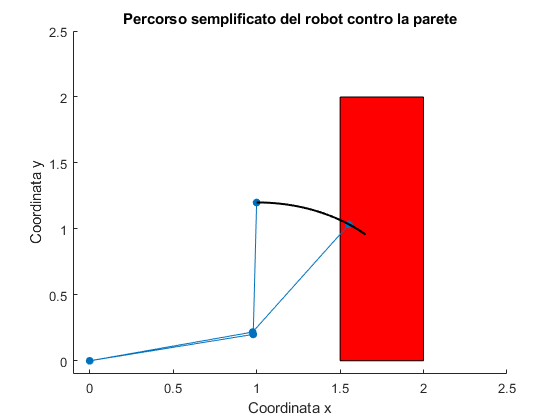

figure                                  % Plotto la "storia" delle configurazioni fino a quella finale
rectangle('Position',[vertice_inferiore spessore_lunghezza],'FaceColor','Red')
hold on
line([O(1,1),C1(1,1),P1(1,1)],[O(2,1),C1(2,1),P1(2,1)],'Marker','.','MarkerSize',20)
line([O(1,1),C2(1,1),Position1(1,1)],[O(2,1),C2(2,1),Position1(2,1)],'Marker','.','MarkerSize',20)
line(POSITION_CT(1,2:length(POSITION_CT)),POSITION_CT(2,2:length(POSITION_CT)),'Color','Black','LineWidth',1.5)
axis([-0.1 2.5 -0.1 2.5])
title('Percorso semplificato del robot contro la parete')
xlabel('Coordinata x')
ylabel('Coordinata y')
hold off

#### Andamento coppia

Trasmessa ai giunti

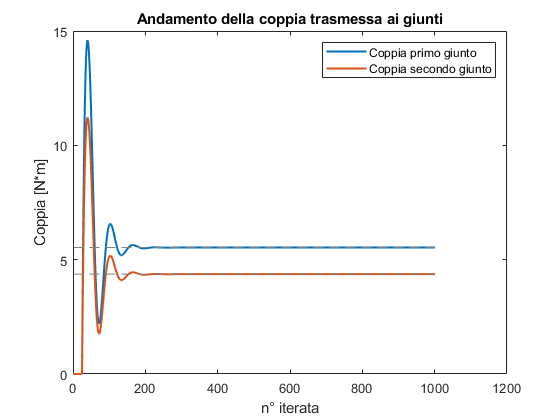

TAU_CT_Finale=TAU_CT(:,1001);
figure                                  % Plotto la "storia" dei valori delle coppie trasmesse ai giunti prima di arrivare alla configurazione finale
plot(TAU_CT','LineWidth',1.5)
hold on
plot(repmat(TAU_CT_Finale',1000,length(TAU_CT)),'color',[0.5 0.5 0.5],'LineStyle','--')    % Plotto la linea asintotica
title('Andamento della coppia trasmessa ai giunti')
legend('Coppia primo giunto','Coppia secondo giunto','Location','northeast')
xlabel('n° iterata')
ylabel('Coppia [N*m]')
hold off

Di controllo

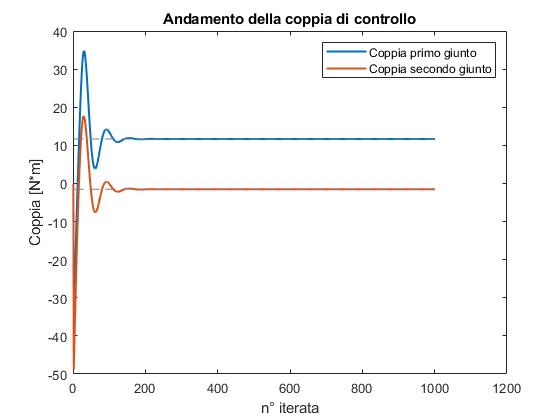

U_CT_Finale_Giunti=U_CT(:,1001);
figure                                  % Plotto la "storia" dei valori delle coppie trasmesse ai giunti prima di arrivare alla configurazione finale
plot(U_CT','LineWidth',1.5)
hold on
plot(repmat(U_CT_Finale_Giunti',1000,length(U_CT)),'color',[0.5 0.5 0.5],'LineStyle','--')    % Plotto la linea asintotica
title('Andamento della coppia di controllo')
legend('Coppia primo giunto','Coppia secondo giunto','Location','northeast')
xlabel('n° iterata')
ylabel('Coppia [N*m]')
hold off

## Controllo della stabilità dei controllori

W=1/2*(dq')*B*dq

W'<=dq'*tau

### Controllore PD

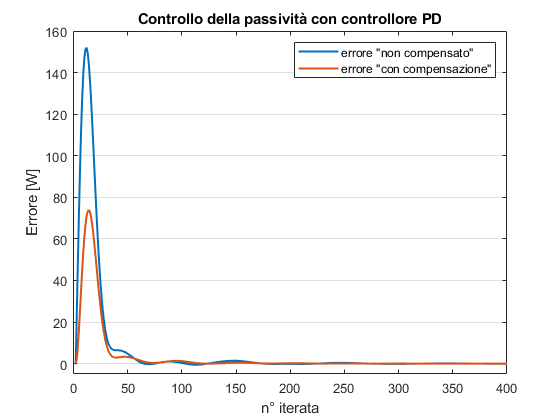

figure                                  % Plotto la "storia" dei valori delle coppie trasmesse ai giunti prima di arrivare alla configurazione finale
plot(ERR1_PD','LineWidth',1.5)
hold on
plot(ERR2_PD','LineWidth',1.5)
set(gca,'XGrid','off','YGrid','on')
xlabel('n° iterata')
ylabel('Errore [W]')
legend('errore "non compensato"','errore "con compensazione"')
title('Controllo della passività con controllore PD')
xlim([-0.5 400])
ylim([-5 160])

### Computer Torque Controller

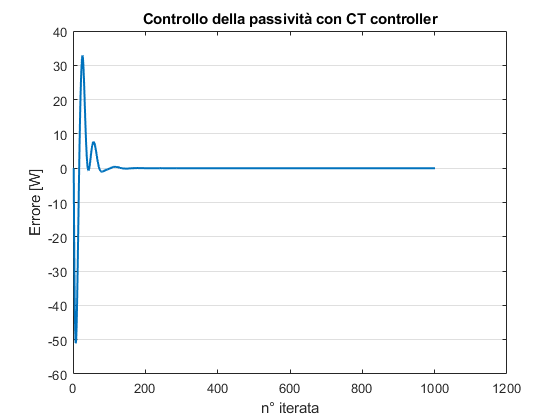

figure                                  % Plotto la "storia" dei valori delle coppie trasmesse ai giunti prima di arrivare alla configurazione finale
plot(ERR1_CT','LineWidth',1.5)
set(gca,'XGrid','off','YGrid','on')
xlabel('n° iterata')
ylabel('Errore [W]')
title('Controllo della passività con CT controller')

Il segno di dW1 dipende dal segno di:

dq

C

B

e 

tau.

C e B sono costruite in maniera tale da essere definite positive, quindi resta che il segno di dW1 dipende unicamente dal prodotto fra dq ed e e da quello fra dq e tau.

## Passificazione del controllore CT

z=2;
Tmin=0.2;
[Passified_Computed_Torque_Results] = Passified_Computed_Torque(q,qA,param,dt,Kp,Kd,maxindex,vertice_inferiore,vertice_superiore,k,z,Tmin);

y_CTP    = Passified_Computed_Torque_Results.Q';
E_CTP    = Passified_Computed_Torque_Results.E;  
dE_CTP   = Passified_Computed_Torque_Results.dE;
ddQ_CTP  = Passified_Computed_Torque_Results.ddQ;
dQ_CTP   = Passified_Computed_Torque_Results.dQ;
Q_CTP    = Passified_Computed_Torque_Results.Q;
U_CTP    = Passified_Computed_Torque_Results.U;
TAU_CTP  = Passified_Computed_Torque_Results.Tau;
ERR1_CTP = Passified_Computed_Torque_Results.ERR1;
POSITION_CTP = Passified_Computed_Torque_Results.POSITION;
Z_CTP = Passified_Computed_Torque_Results.Z;
ALFA = Passified_Computed_Torque_Results.ALFA;
PHI = Passified_Computed_Torque_Results.PHI;
GAMMA = Passified_Computed_Torque_Results.GAMMA;
dKvf = Passified_Computed_Torque_Results.DK;

figure                                  % Plotto la "storia" dei valori degli angoli raggiunti prima di arrivare alla configurazione finale
plot(y_CTP,'LineWidth',1.5)
hold on
plot(repmat(qA,1,length(y_CTP))','color',[0.5 0.5 0.5],'LineStyle','--')
title('Andamento degli angoli verso la configurazione finale')
legend('Theta1','Theta2','Location','northeast')
xlabel('n° iterata')
ylabel('Angolo [rad]')
hold off



figure                                  % Plotto la "storia" delle configurazioni fino a quella finale
rectangle('Position',[vertice_inferiore spessore_lunghezza],'FaceColor','Red')  % Blocco per rappresentare la parete
hold on
line(POSITION_CTP(1,2:length(POSITION_CTP)),POSITION_CTP(2,2:length(POSITION_CTP)),'Color','Black','LineWidth',1.5)   % Vettore con la posizione dell'end effector ad ogni iterata

for jj=2:20:length(POSITION_CTP)-700         % Raffiguro le configurazioni del robot ogni 15 iterate, fino alla 300sima iterata, ovvero quella in cui la posizione sembra stabilizzarsi
    [theta1P,theta2P,theta1A,theta2A,O,C1,C2,P1,Position1P] = get_theta(P,POSITION_CTP(:,jj),param);

    line([O(1,1),C2(1,1),Position1P(1,1)],[O(2,1),C2(2,1),Position1P(2,1)],'Marker','.','MarkerSize',20)  % Blocco per rappresentare la configurazione
end

axis([-0.1 2.5 -0.1 2.5])
title('Percorso del robot contro la parete')
xlabel('Coordinata x')
ylabel('Coordinata y')
hold off

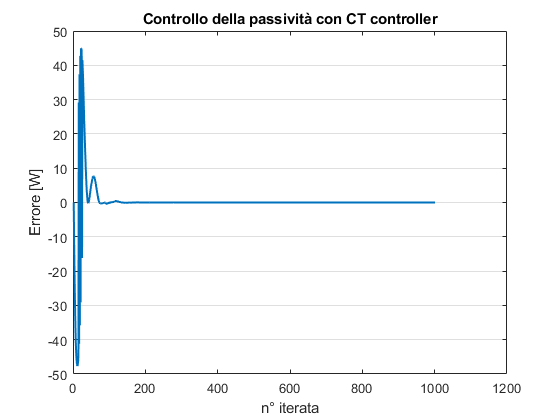

figure                                  % Plotto la "storia" dei valori delle coppie trasmesse ai giunti prima di arrivare alla configurazione finale
plot(ERR1_CTP','LineWidth',1.5)
set(gca,'XGrid','off','YGrid','on')
xlabel('n° iterata')
ylabel('Errore [W]')
title('Controllo della passività con CT controller')

#### Andamento dell'energia stoccata nel tank

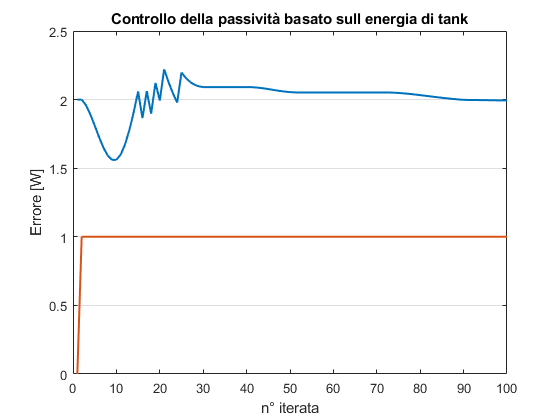

figure                                  % Plotto la "storia" dei valori delle coppie trasmesse ai giunti prima di arrivare alla configurazione finale
plot(Z_CTP','LineWidth',1.5)
hold on
plot(ALFA','LineWidth',1.5)
%plot(PHI'+1.3,'LineWidth',1.5)
%plot(GAMMA'+2.5,'LineWidth',1.5)
%plot(dKvf','LineWidth',1.5)
set(gca,'XGrid','off','YGrid','on')
xlabel('n° iterata')
ylabel('Errore [W]')
title('Controllo della passività basato sull energia di tank')
xlim([0 100])